# Module 3 Project

## Segment an Image with Code

In this module’s project, your goal is to segment an image with different-colored puzzle pieces into three labels: one for the background, one for the blue puzzle pieces, and one for the red/orange puzzle pieces.

Your code will need to do the following. 

- Create a binary mask that separates the background from the puzzle pieces. You can use this mask directly to label background pixels and/or to create a masked image to work on. 

- Create a segmented image with 3 labels. The final result should only contain the values 1, 2, and 3 for the different labels. 

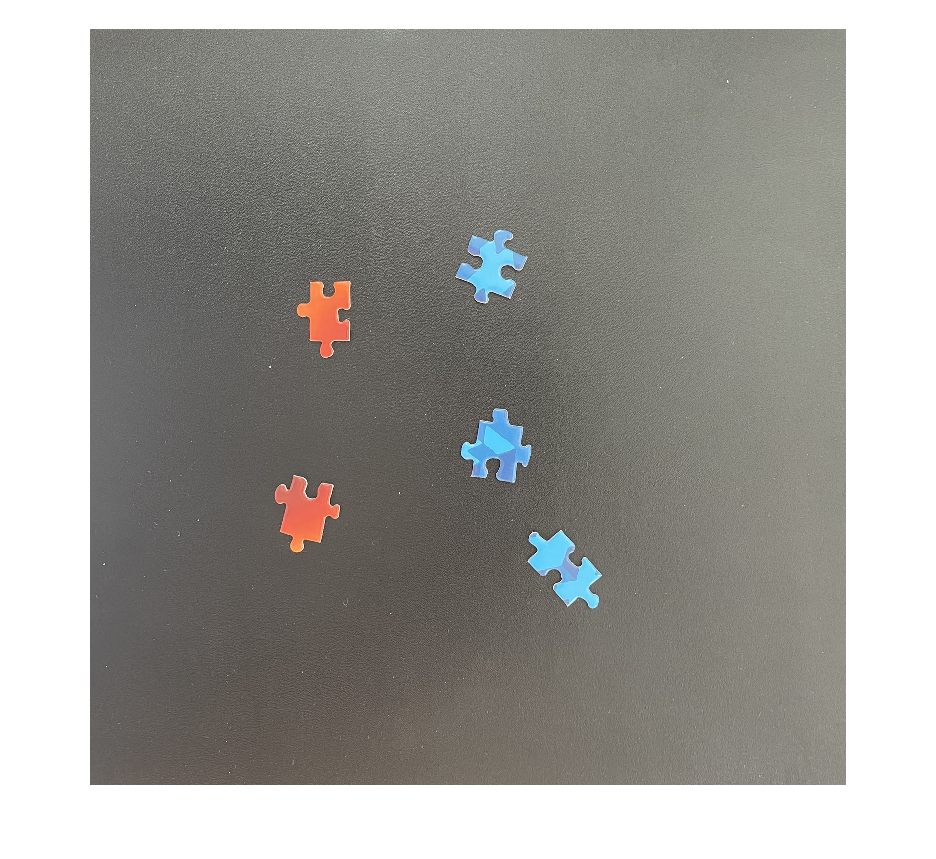

img = imread("Puzzle_06.jpg");
imshow(img)

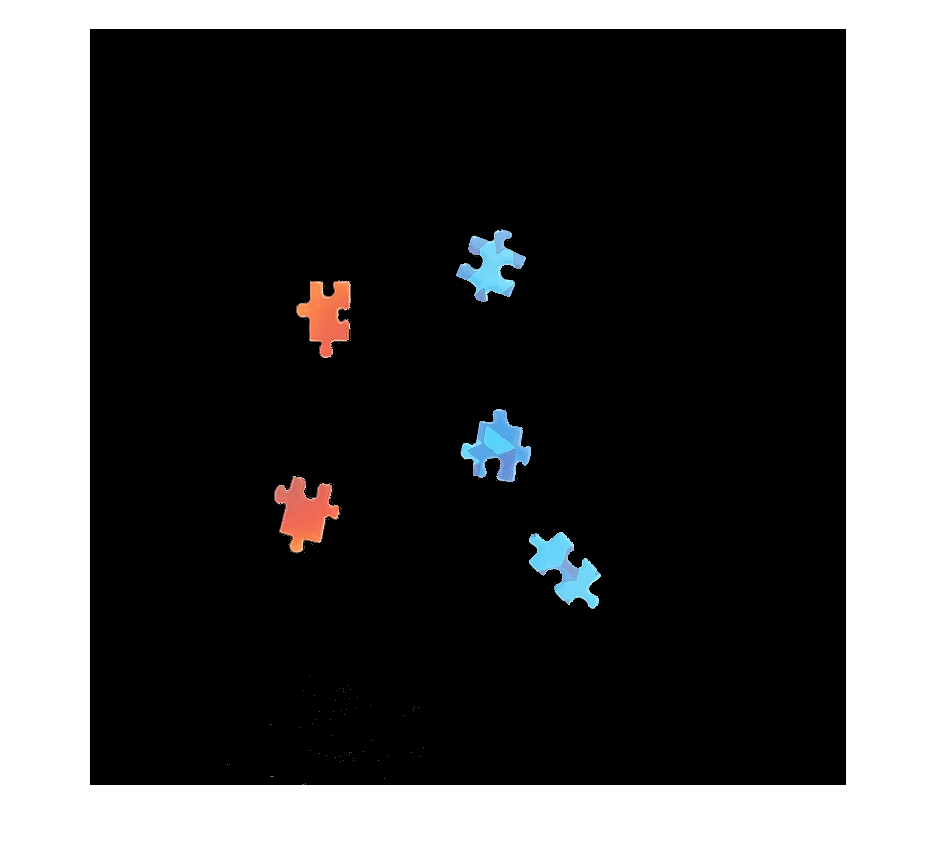

HSV = rgb2hsv(img);
chipmask = HSV(:,:,2) > 0.2; 
HSVchip = HSV; 
HSVchip(~repmat(chipmask,1,1,3)) = 0; 
RGB = hsv2rgb(HSVchip);
imshow(RGB)

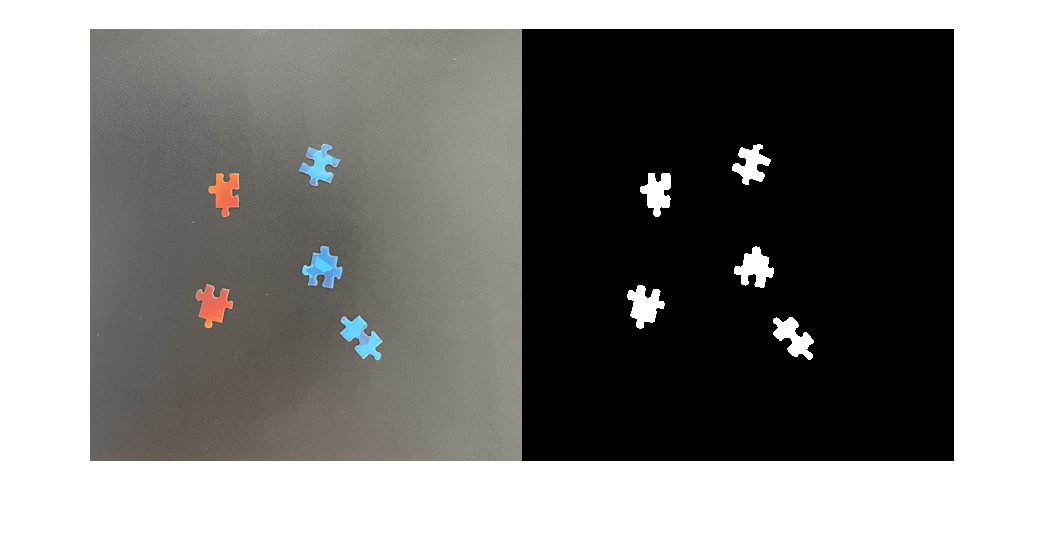

BW = im2gray(RGB) > 0;
BW = imcomplement(BW);
se = strel("disk",5,0);
BW = imdilate(BW,se);
BW = imerode(BW,se);
BW = imcomplement(BW);
montage({img, BW})

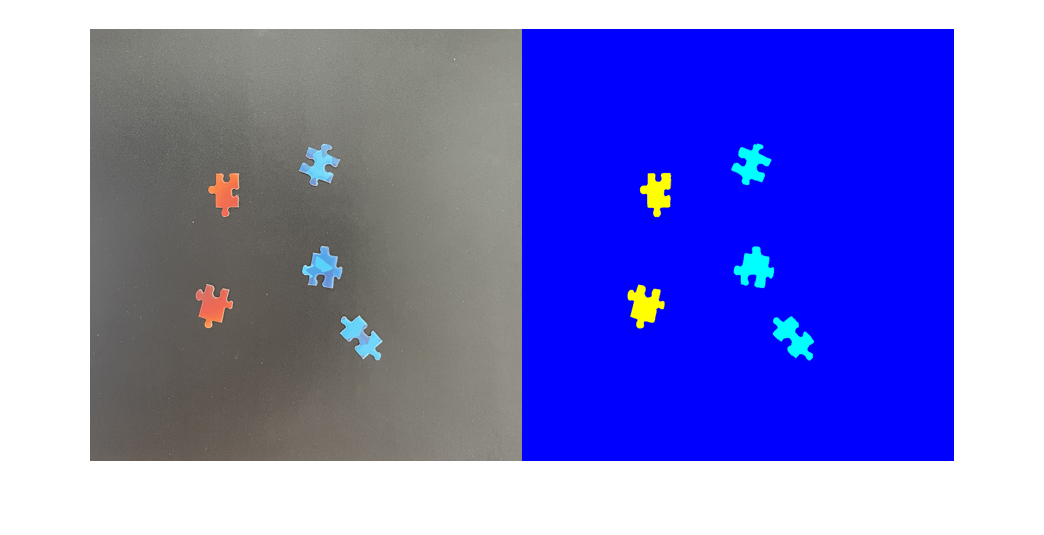

K = 3; 
labels = imsegkmeans(im2single(HSVchip),K);
montage({img,label2rgb(labels)})